%Exercicio 1
filepath = 'C:\Users\User\Desktop\uni\ATD\escala.wav'

filepath = 'C:\Users\User\Desktop\uni\ATD\escala.wav'

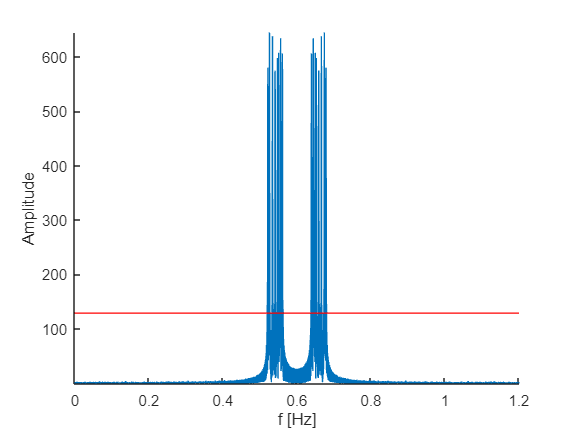

[sinal_audio,fs] = audioread(filepath);
N = length(sinal_audio);
Omega0 = 2*pi/N;
DeltaF = fs/N;
Ts = 1/fs;

X = fftshift(fft(sinal_audio));

if(mod(N,2) == 0)
    f = -fs/2:fs/N:fs/2-fs/N;
else
    f = -fs/2+fs/(2*N):fs/N:fs/2-fs/(2*N);
end
X = abs(X);


t = linspace(0,(N-1)/fs,N);
max_x = max(X);
min_mag = 0.2*max_x;
figure(1);
hold on;
plot(t,X);
plot(t,repmat(min_mag,N,1),'r');
axis tight;
xlabel('f [Hz]');
ylabel('Amplitude');
hold off;

[pks,locs] = findpeaks(X,'MinPeakHeight',min_mag);
f_relevant = f(locs)

f_relevant =  -532.8893 -522.8976 -513.7386 -512.0733 -503.7469 -493.7552 -449.6253 -440.4663 -430.4746 -402.1649 -400.4996 -393.0058 -359.7002 -348.0433 -341.3822 -329.7252 -318.9009 -312.2398 -304.7460 -293.9217 -283.0974 -269.7752 -262.2814 -253.1224 -251.4571  251.4571  253.1224  262.2814  269.7752  283.0974  293.9217  304.7460  312.2398  318.9009  329.7252  341.3822  348.0433  359.7002  393.0058  400.4996  402.1649  430.4746  440.4663  449.6253  493.7552  503.7469  512.0733  513.7386  522.8976  532.8893


f_relevant = f_relevant(f_relevant>0)

f_relevant =   251.4571  253.1224  262.2814  269.7752  283.0974  293.9217  304.7460  312.2398  318.9009  329.7252  341.3822  348.0433  359.7002  393.0058  400.4996  402.1649  430.4746  440.4663  449.6253  493.7552  503.7469  512.0733  513.7386  522.8976  532.8893


f_relevant = round(f_relevant)

f_relevant =    251   253   262   270   283   294   305   312   319   330   341   348   360   393   400   402   430   440   450   494   504   512   514   523   533


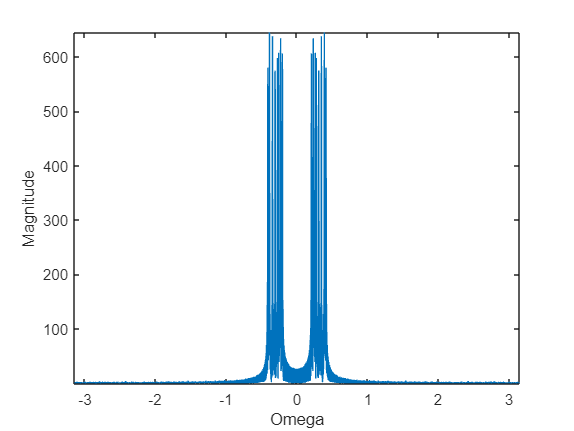


if(mod(N,2)==0)
    Omega = -Omega0*N/2:Omega0:Omega0*N/2-Omega0;
else
    Omega = -Omega0*N/2 + Omega0/2:Omega0:Omega0*N/2 - Omega0/2;
end

figure(3);
plot(Omega,X);
axis tight;
xlabel('Omega');
ylabel('Magnitude');
hold off;


Omega_relevant = Omega(locs);
Omega_relevant = Omega_relevant(Omega_relevant>0);

tabNotas = {'Do','Dosust','Re','Resust','Mi','Misust','Fa','Fasust','Sol','Solsust','La','Lasust','Si';262,277,294,311,330,349,370,392,415,440,466,494,523}

tabNotas = 2×13 cell array
    {'Do' }    {'Dosust'}    {'Re' }    {'Resust'}    {'Mi' }    {'Misust'}    {'Fa' }    {'Fasust'}    {'Sol'}    {'Solsust'}    {'La' }    {'Lasust'}    {'Si' }
    {[262]}    {[   277]}    {[294]}    {[   311]}    {[330]}    {[   349]}    {[370]}    {[   392]}    {[415]}    {[    440]}    {[466]}    {[   494]}    {[523]}



for i = 1:numel(f_relevant)
    sprintf("%d Hz-->%s",f_relevant(i),tabNotas{1,find([tabNotas{2,:}] == f_relevant(i))});
end

%Exercicio2


